**Submitted By**

**Hridya Divakaran : V00970167**

**Sanjana Arora : V00966221 **

clear memory;
clearvars;
clc;

**Q1 Load the Exercise 4 data set. This data comprises 1000 samples from 2 classes in 100 measurement dimensions.**


% loading the Exercise 4 data set
load('Exercise_4_Data.mat')
whos;

  Name               Size               Bytes  Class     Attributes

  Test_indx          1x750               6000  double              
  Train_indx         1x250               2000  double              
  a               1000x100             800000  double              
  classes            1x1000              8000  double              



**Q2 Comment on whether the available data represents a dense sampling of this high dimensional space and, if you assumed both data classes were Gaussian distributed, then discuss how many data samples would be required to provide a sufficient dense sampling of the data across all of its dimensions.**

**Ans. **The available data does not represent a dense sampling of high dimensional space as only 1000 data samples are provided for 100 measurement dimensions. Let's say, for providing a sufficient dense sampling of the  gaussian data that requires 100 samples for representation in 1 dimension, to represent the same gaussian data across all of its 100 dimensions, 100^100 data samples would be required. Similarly, to provide a sufficient dense sampling of data across all of its dimensions we would require way higher number of samples than the provided 1000 data samples.

**Q3 Randomly partition the data into training and test sets where the training set represents 25% of the data and the test set represents the remaining 75% of the data.**

% variable "a" represents the total dataset of the Exercise 4 file
data = a;

% Testing and Training Dataset
% Train index captures 25% of the dataset
% Test index captures 75% of the dataset
training_data = a(Train_indx, :);
testing_data = a(Test_indx, :);


% Data Labels captured in the "classes" variable of the dataset
train_label = classes(Train_indx);
test_label = classes(Test_indx);

**Q7 Use the training data to construct a Fisher Linear Discriminant and use the learned discriminant to reduce the test data to one dimension.**

% data with label = 0
class0_index = find(train_label == 0);
training_data_0 = training_data(class0_index, :);

% mean of the zero label data
mu0 = mean(training_data_0);


% data with label == 1
class1_index = find(train_label == 1);
training_data_1 = training_data(class1_index, :);

% mean of the 1 label data
mu1 = mean(training_data_1);


% mean of whole training dataset
mu_data = mean(training_data, 2);

% Compute the In-class scatter matrices
delta_0 = training_data_0' - mu0';
delta_1 = training_data_1' - mu1';
Sw_0 = delta_0 * delta_0';
Sw_1 = delta_1 * delta_1';
Sw = Sw_0 + Sw_1;

% Calculate the between-class scatter matrix
deltab_0 = ((mu0' - mu_data') * (mu0' - mu_data')');
deltab_1 = ((mu1' - mu_data') * (mu1' - mu_data')');
Sb = deltab_0 + deltab_1;

[V_FLD, D] = eig(Sb,Sw);
[ ~ , idx_eig ] = sort( diag(D) , 'descend' );
idx_keep = idx_eig( 1 : 1 );
w_FLD = V_FLD(: , idx_keep );

% dimensionally reduced training and test dataset
onedim_training_data = (w_FLD' * training_data')';
onedim_testing_data = (w_FLD' * testing_data')';

% Normalize the dataset
onedim_training_data = onedim_training_data + 3.98*10^10;
onedim_testing_data = onedim_testing_data + 3.98*10^10;

**Q8 Apply Bayes classification on the dimensionality reduced test data and comment on the classification performance.**

% datapoints with label 0 in dimensionally reduced dataset
training_data_0_1dim = onedim_training_data(class0_index, :);

class_0_testingindex = find(test_label == 0);
testing_data_0_1dim = onedim_testing_data(class_0_testingindex,:);


% datapoints with label 1 in dimensionally reduced dataset
training_data_1_1dim = onedim_training_data(class1_index, :);
class_1_testingindex = find(test_label == 1);
testing_data_1_1dim = onedim_testing_data(class_1_testingindex,:);

## Bayes Classifier

% Calculate mean and variance
mu_training_0_1dim = mean(training_data_0_1dim);
mu_training_1_1dim = mean(training_data_1_1dim);
var_training_0_1dim = 0.01;
var_training_1_dim = 0.01;

% Calculate the a priori probability for each class in the training data set
prior_prob0 = length(training_data_0) / length(training_data);
prior_prob1 = length(training_data_1) / length(training_data);

% Calculate the discriminant function values of a data point for classes 0 and 1 respectively in the testing data set
gk_0 = discriminant_fn(mu_training_0_1dim, var_training_0_1dim, prior_prob0,onedim_testing_data);
gk_1 = discriminant_fn(mu_training_1_1dim, var_training_1_dim, prior_prob1,onedim_testing_data);

% Index array for each class
bound_0 = find(gk_0 > gk_1);
bound_1 = find(gk_1 > gk_0);
decision = repmat([2], length(onedim_testing_data), 1);
decision(bound_0, :) = 0; 
decision(bound_1, :) = 1;
output_label = decision; 

% Calculate the performance of Bayes calssifier based on Fisher Linear Discriminant
error_Fischer = sum(output_label ~= test_label')

error_Fischer = 0


% Array containing data points for each class
result_0_1dim = onedim_testing_data(bound_0, :);
result_1_1dim = onedim_testing_data(bound_1, :);

% Plot the class 0, 1 regions
plot(result_0_1dim, '.red')
hold on;
plot(result_1_1dim, '.blue')
title('Bayes classifier on FLD reduced data')
legend('class 0', 'class 1')
hold off;

**Q8 Discussion**

The number of wrongly classified data samples after reducing the data using Fischer Linear Discriminant analysis is zero. Therefore, the Fischer Linear Discriminant analysis is working really well for the given dataset. This is because the Fischer Linear Discriminant analysis provides the valuable information required for data classification and the direction of the projected data is such that the Bayes Classifier is able to classify the data correctly. 

**Q9 Discuss the characteristics of the resulting dimensionality reduction vector and the Fisher-based approach was able to classify the data versus the results obtained for the PCA-based approach.**

Ans. From the number of wrongly classified samples after using PCA and Fischer based approach, it is quite evident that Fischer based approach is better amongst the two approaches for classifying the data. It is attributed to the fact that PCA projects the data onto the eigen vector as shown in the below figure and that eigen vector does not provide the direction that could help in classifying the data. 

                 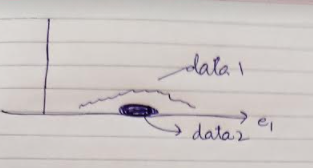

Whereas as shown in Figure below, if we project that data in the direction of eigen vector obtained from Fischer Linear Discriminant, discrimination between the data 1 and 2 would be easier. Fischer Linear Discriminant gives a better way to find a better projection direction because, it chooses the projection direction w that maximizes the ratio of between-class scatter to the within-class scatter and thus, with a higher between-class distance, Fischer Linear Discriminant is able to project the data such that it is easier to discriminate between the two classes and as a result, Bayes Classifier is able to classify the data correctly.The Fischer approach finds a vector W, projects the data onto axis ( x.W) so that the data is well separated.

                        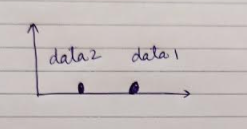

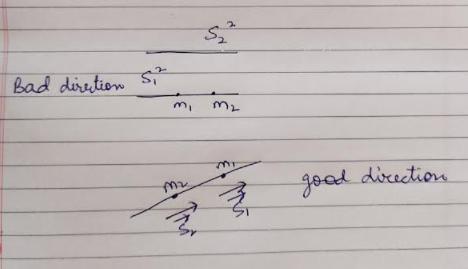

**10. Discuss whether the performance of PCA would have improved if a higher percentage of the data was used in training the PCA system.**

Answer: PCA is very useful in reducing the dimensionality of the data, however, its not an ideal method for classification problems. It is not necessary that adding more data would improve the classification performance because with all the more number of sample data, PCA would still continue to find the variance among the features and project the data on the axis provided by the eigen vector that does not provide information that is useful for classification. The selected features may still miss the most crucial information required for performing the classification of the dataset and the classification on the data reduced by PCA may continue to be incorrect.

**Q13  Now remove the feature vector identified through the Fisher analysis and retrain a new neural network based on this data. Discuss the classification performance that this classifier achieves and the overall distribution of classification performances that such a classifier could be seen to achieve.**

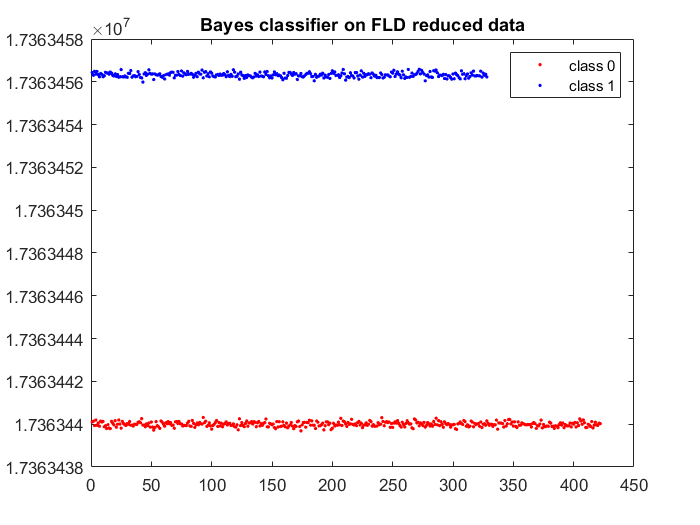

%Creating new dataset for Neural Network by removing
%feature with most information
[max_value, index] = max(abs(V_FLD(:, 1)));

% Delete the eigenvector which contains the most informative feature for classification
data(:, index) = [];

index_training = Train_indx;
index_testing = Test_indx;
training_reduceddata = data(index_training, :);
testing_reduceddata = data(index_testing, :);
label_train = classes(index_training);
label_test = classes(index_testing);
combined_label_AB = [label_train, label_test];

inputs = training_reduceddata';
targets = index_training;


% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize);
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

% Train the Network
[net,tr] = train(net,inputs,targets);



%Run the neural network with Testing data
outputs_test = net(testing_reduceddata');
epsilon_NN_1 = 1e-4;
region_1 = find(abs(outputs_test' - 1) < epsilon_NN_1);
region_0 = find(abs(outputs_test' - 0) < epsilon_NN_1);
matrix_1 = repmat([2], length(outputs_test), 1);
matrix_1(region_0, :) = 0; 
matrix_1(region_1, :) = 1;
result_label = matrix_1; 

% Calculate the performance of Neural Network classifier 
% after removing the feature vector identified through the Fisher analysis
classification_error_NN = sum(label_test' ~= result_label)

classification_error_NN = 750

**Q13 Discussion**

Here we can see that when we removed the feature vector identified through Fisher analysis, neural nework fails very badly, because for performing classification we need the valuable infromation of this removed vector. There is only one dimension and other dimensions did'nt have much classification information.Thus, without this one dimension the neural network failed. If this input data would have had this one dimension the neural network would have classified the data correctly.

** Q14 Discuss whether it would be common in operational data analysis settings for dense data samplings to be available a priori from which analytics systems could then be trained or whether this is more likely to occur rarely. Discuss the implications this has one training data analytics systems and, particularly, the selection of measurement features based on the analyses of available data.**

Answer: Dense data samplings are uncommon in operational data analysis. Let's say, for providing a sufficient dense sampling of the  gaussian data that requires 100 samples for representation in 1 dimension, to represent the same gaussian data across all of its 100 dimensions, 100^100 data samples would be required. Instead, we only have 1,000 data samples to work with. In operational data analaysis settings, we have similar issues of data sparsity. For the data provided for this exercise, many of the dimensions are irrelevant because they do not provide useful information for classification, and we can further lower the number of dimensions to identify the feature having useful information for classification.

Suppose we are given four classes, 200 features, and 2 million data points in operational data analysis. We just do not have enough data if all or most of these 200 features are significant for classification. If many features are uninformative and the dimensionality can be reduced to less than 10, then 2 million data samples will enough. Therefore, depending on the kind of information being provided by the features, data sparsity could be an issue for performing data classification.

function g_x = discriminant_fn(mu,sigma,prior_prob,x) 
    w1 = (-1/2)*inv(sigma);
    
    w2 = inv(sigma)*mu;
    
    w3 = (-1/2)*mu'*inv(sigma)*mu - (1/2)*log(det(sigma)) + log(prior_prob);
        
    g_x = sum((x*w1.').*x,2).' + w2'*x' + w3;
    

end 